# MATLAB Föreläsning 8

For att kunna köra denna fil i MATLAB, behover ni implementera ODE-lösarna och några av funktionerna själva

## Exempel 14.1 i Jönsson

Plotta analytiska lösningar till ekvationen


$$y'(t) = -2ty(t)$$


Lösningar till ekvationen är $y(t) = ce^{-t^2}$. Konstaten c kan bestämmas genom ett vilkor, t.ex. $y(0)  = 1$ ger $c = 1.$

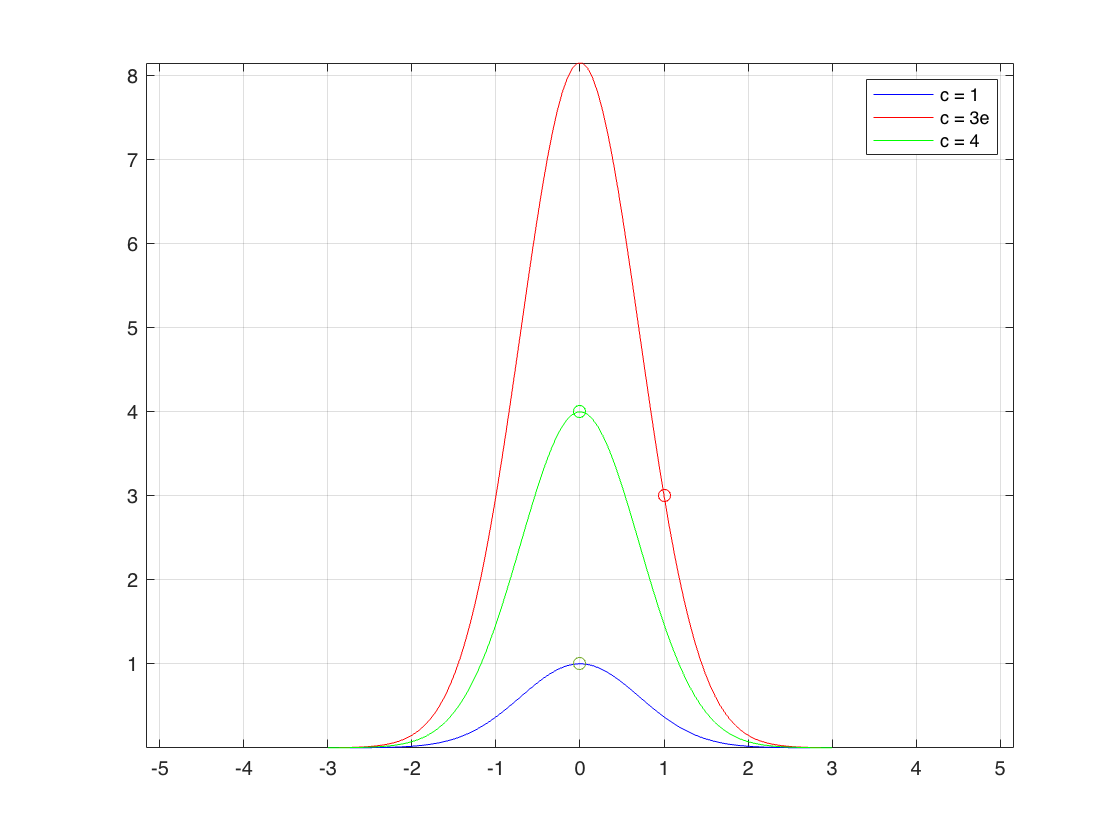

clear 
t = linspace(-3,3,100);
c1 = 1;
c2 = 3*exp(1);
c3 = 4;

y1 = c1*exp(-t.*t);
y2 = c2*exp(-t.*t);
y3 = c3*exp(-t.*t);

clf 
plot(t,y1,'b')
hold on 
plot(t,y2,'r')
plot(t,y3,'g')
plot(0,4,'go')
plot(0,1,'o')
plot(1,3,'ro')

grid on
axis equal
legend('c = 1', 'c = 3e', 'c = 4')

## Fö exempel 1

Plotta analytiska lösningar till $y' = y$ med $y(0) = c$. Lösningar till ekvationen är $y(t) = ce^t$.

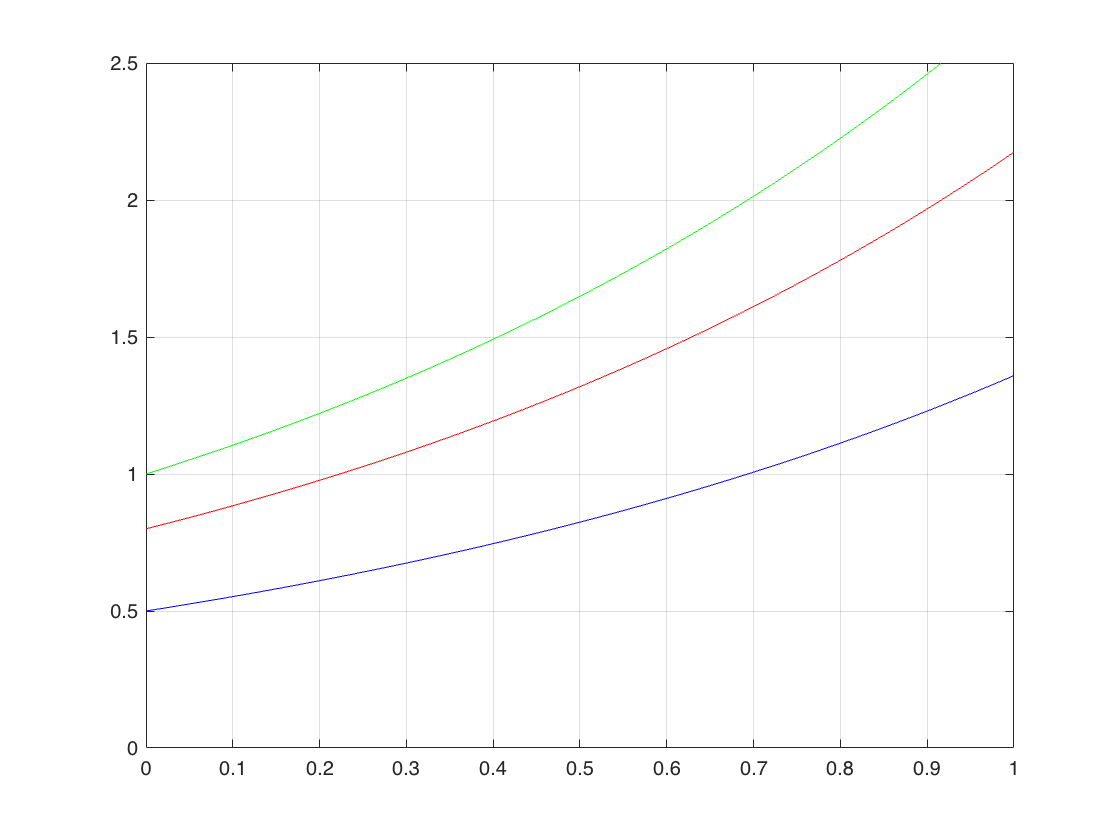

clear 
t = linspace(0,1,100);

% Välj tre olika begynnelsevillkor:
c1 = 0.5;
c2 = 0.8;
c3 = 1;

y1 = c1*exp(t);
y2 = c2*exp(t);
y3 = c3*exp(t);

clf
plot(t,y1,'b')
hold on 
grid on
plot(t,y2,'r')
plot(t,y3,'g')
ylim([0,2.5])

Analytiska och numeriska lösningar till $y' = y$ med $y(0) = 1$

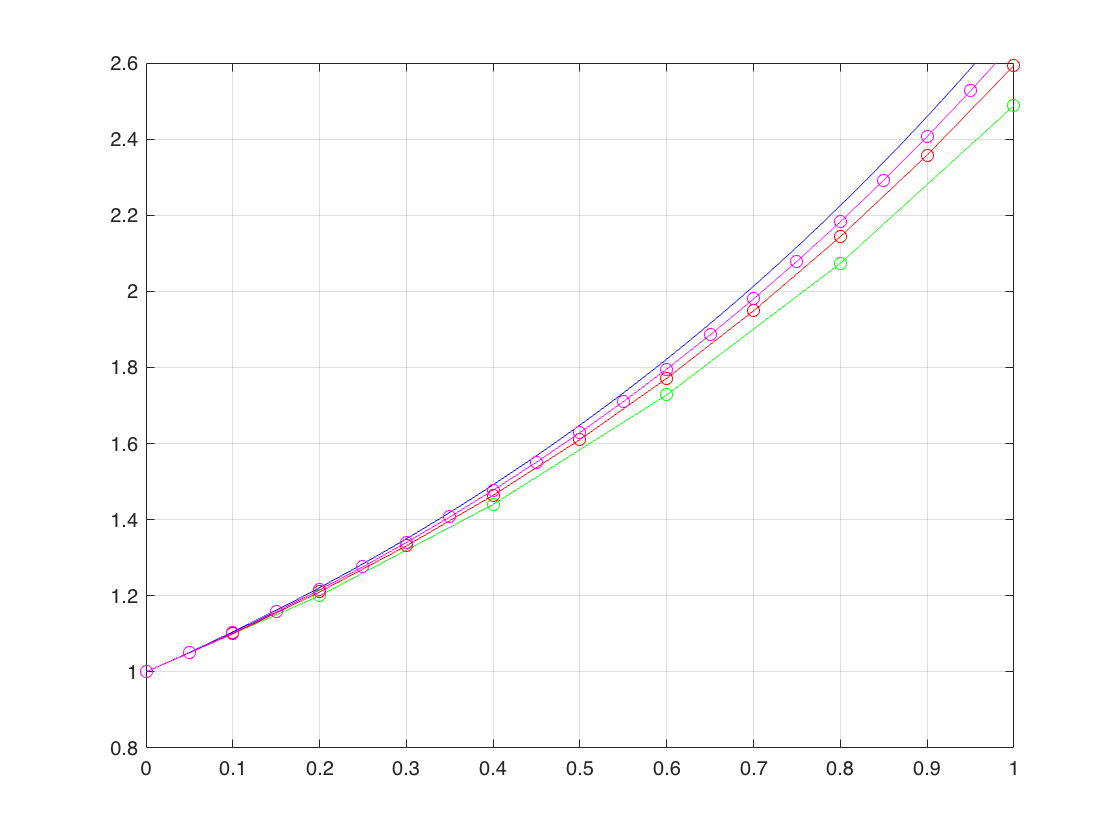

clear 
t = linspace(0,1,100);
c = 1;

% analytisk lösning
y = c*exp(t);

% numeriska lösningar med Euler och tre olika diskretiseringar
[t1,y1]  = odeEuler(@funkEx1,[0,1],1,5);
[t2,y2]  = odeEuler(@funkEx1,[0,1],1,10);
[t3,y3]  = odeEuler(@funkEx1,[0,1],1,20);

clf
plot(t,y,'b')
grid on 
hold on
plot(t1,y1,'g-o')
plot(t2,y2,'r-o')
plot(t3,y3,'m-o')
ylim([0.8,2.6])

Visualisering av globala trunkeringsfelet vid halvering av steglängden. 

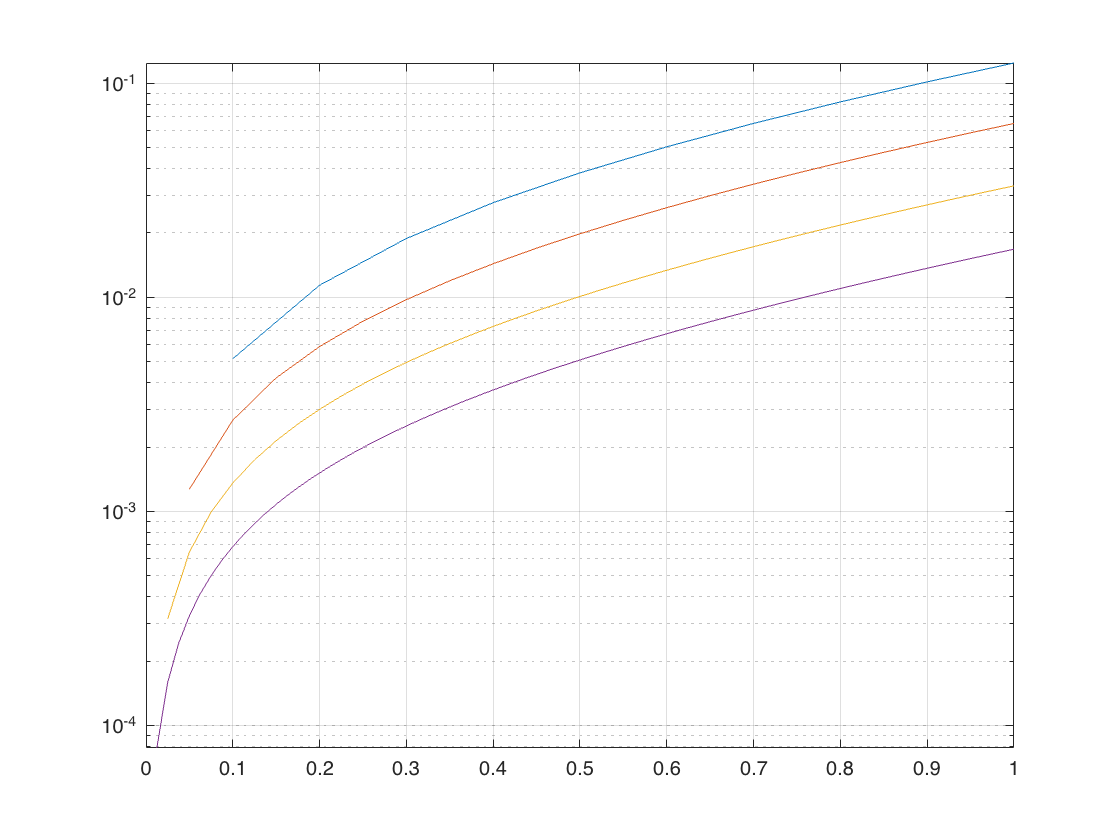

clear 

% lös ode'n med Eulers metod, använd n = 10, 20, 40, 80.
[t1,y1]  = odeEuler(@funkEx1,[0,1],1,10);
[t2,y2]  = odeEuler(@funkEx1,[0,1],1,20);
[t3,y3]  = odeEuler(@funkEx1,[0,1],1,40);
[t4,y4]  = odeEuler(@funkEx1,[0,1],1,80);

% Beräkna analytiskt, fuktionsvärden för motsvarande tidssteg
c = 1;
ye1 = c*exp(t1);
ye2 = c*exp(t2);
ye3 = c*exp(t3);
ye4 = c*exp(t4);
% Beräkna absolutbeloppet av skillnaden 
fel1 = abs(ye1 - y1);
fel2 = abs(ye2 - y2);
fel3 = abs(ye3 - y3);
fel4 = abs(ye4 - y4);

% Plotta 
clf
semilogy(t1,fel1)
hold on
grid on
semilogy(t2,fel2)
semilogy(t3,fel3)
semilogy(t4,fel4)


disp('Facktor forbattring av felet vid halvering av steglängden')

Facktor forbattring av felet vid halvering av steglängden


mean(fel1)/mean(fel2)

ans = 1.9554

mean(fel2)/mean(fel3)

ans = 1.9767

mean(fel3)/mean(fel4)

ans = 1.9881

## Fö exempel 2

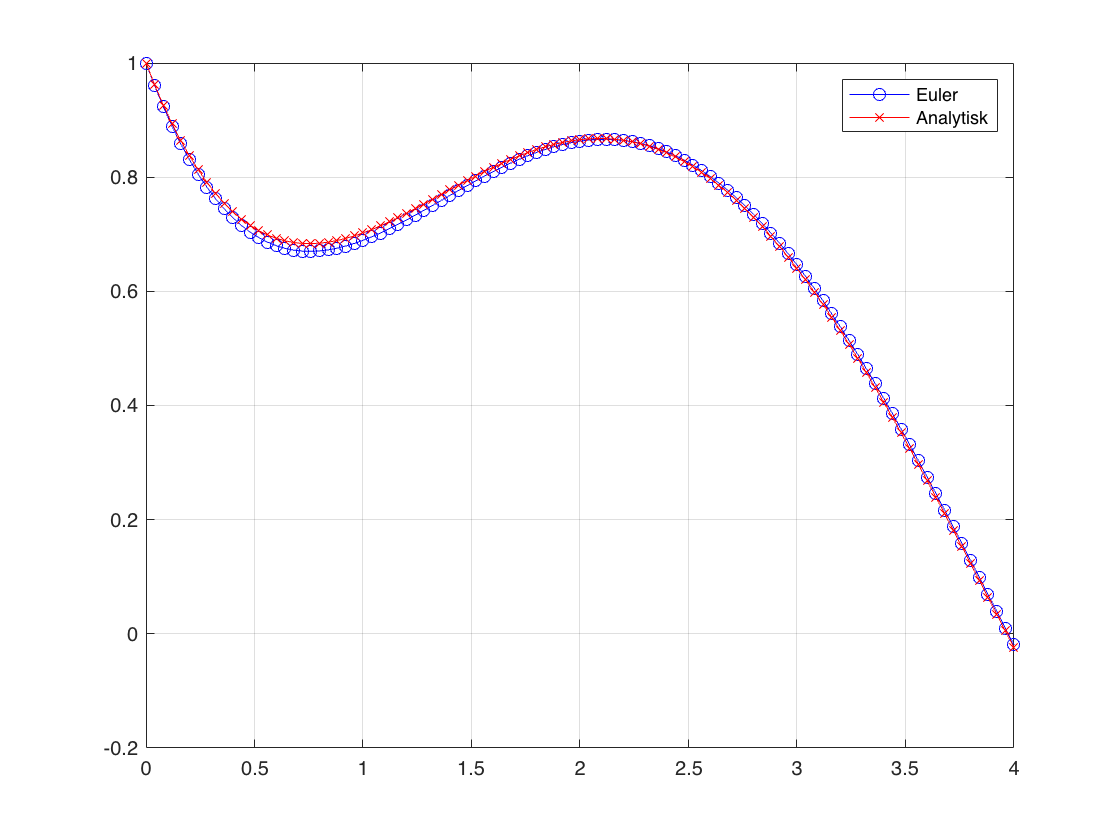

clear 
y0 = 1;
tspan = [0; 4];
n = 100;

[t1,y1] = odeEuler(@funkEx2,tspan,y0,n);
clf
plot(t1,y1,'b-o') 
grid on

yf = sin(t1)/2 - cos(t1)/2 + 3/2*exp(-t1);
hold on
plot(t1,yf,'r-x')
hold off
legend('Euler','Analytisk')

## Fö exempel 3

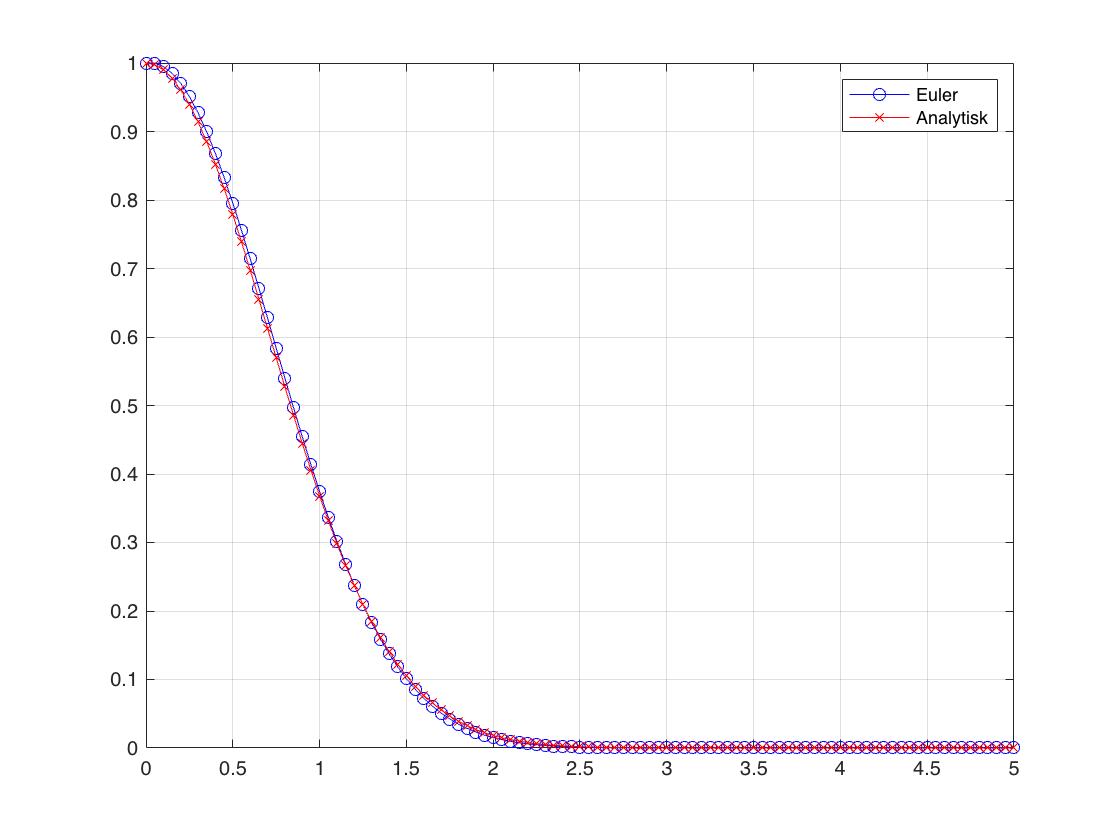

clear 
y0 = 1;
tspan = [0,5];
n = 100;

[t1,y1] = odeEuler(@funkEx3,tspan,y0,n);
plot(t1,y1,'b-o') 
grid on

% Begynnelsevillkor y0 = 1 => c = 1
c = 1;
ye = c*exp(-t1.*t1);
hold on
plot(t1,ye,'r-x') 
hold off
legend('Euler','Analytisk')

## Jämför Euler med Runge-Kutta ordning 2

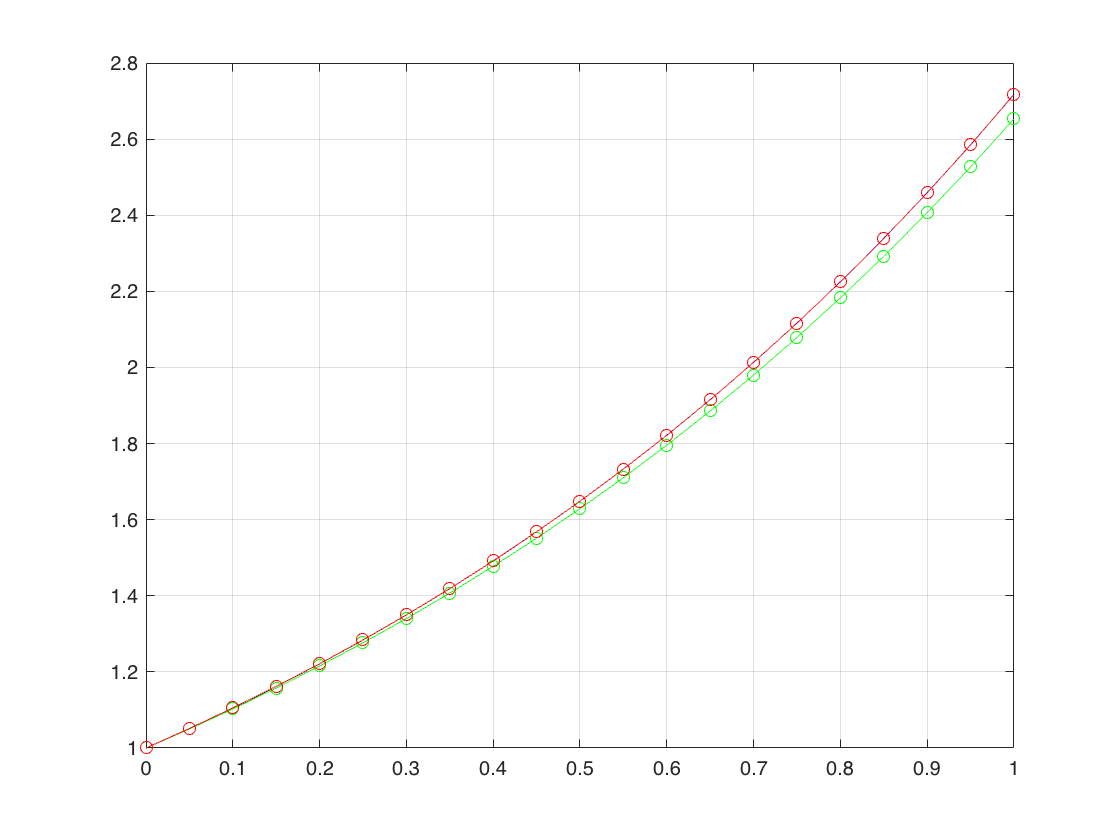

clear 
t = linspace(0,1,100);
c = 1;
y = c*exp(t);
n = 20;

% Berakna numeriska losningar 
[t1,y1]  = odeEuler(@funkEx1,[0,1],1,n);
[t2,y2]  = odeEuler(@funkEx1,[0,1],1,2*n);
[t5,y5]  = odeEuler(@funkEx1,[0,1],1,4*n);
[t3,y3]  = odeRK2(@funkEx1,[0,1],1,n);
[t4,y4]  = odeRK2(@funkEx1,[0,1],1,2*n);
[t6,y6]  = odeRK2(@funkEx1,[0,1],1,4*n);
[t7,y7]  = odeRK4(@funkEx1,[0,1],1,2*n);
% Plotta och jamfor 
clf
plot(t,y,'b')
grid on 
hold on
plot(t1,y1,'g-o')
plot(t3,y3,'r-o')

## Jamfor globalt fel i Euler och RK-2

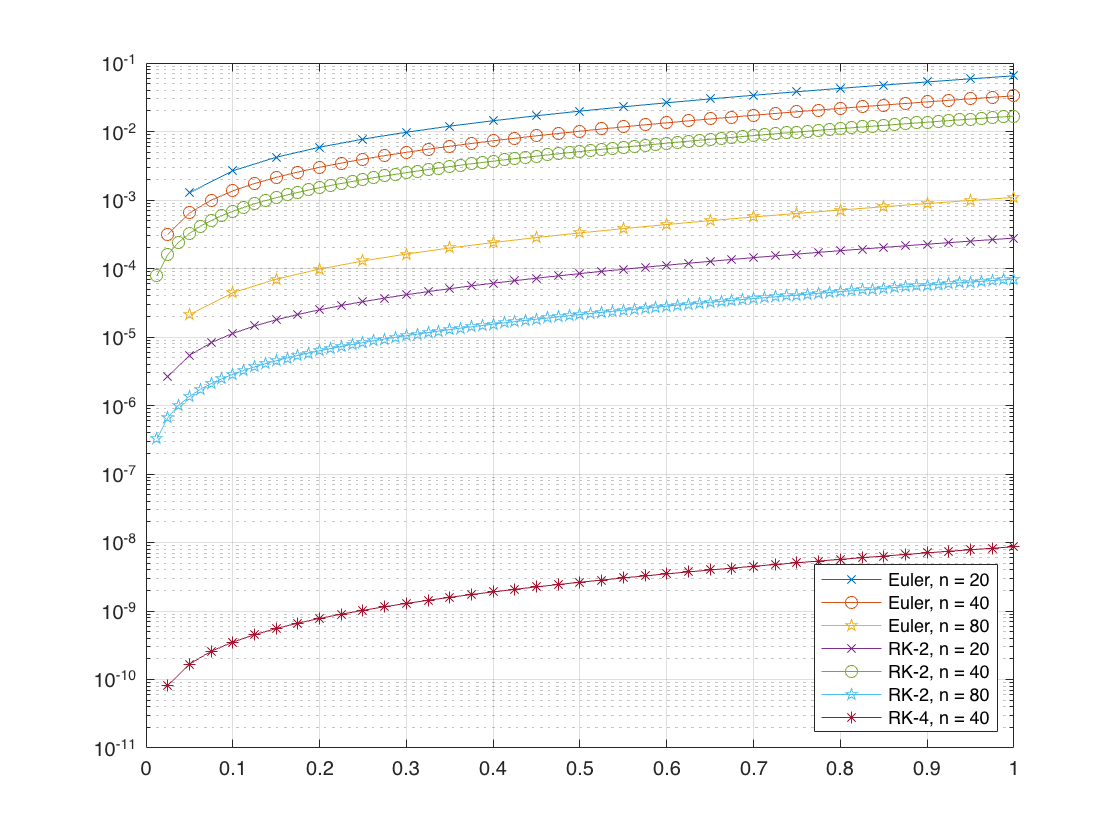

ye1 = c*exp(t1);
ye2 = c*exp(t2);
ye3 = c*exp(t3);
ye4 = c*exp(t4);
ye5 = c*exp(t5);
ye6 = c*exp(t6);
ye7 = c*exp(t7);

fel1 = abs(ye1 - y1);
fel2 = abs(ye2 - y2);
fel3 = abs(ye3 - y3);
fel4 = abs(ye4 - y4);
fel5 = abs(ye5 - y5);
fel6 = abs(ye6 - y6);
fel7 = abs(ye7 - y7);
clf
semilogy(t1,fel1,'-x')
hold on
grid on
semilogy(t2,fel2,'-o')
semilogy(t3,fel3,'-p')

semilogy(t4,fel4,'-x')
semilogy(t5,fel5,'-o')
semilogy(t6,fel6,'-p')
semilogy(t7,fel7,'-*')

hold off
legend('Euler, n = 20', 'Euler, n = 40', 'Euler, n = 80', ...
    'RK-2, n = 20', 'RK-2, n = 40', 'RK-2, n = 80', ...
    'RK-4, n = 40','Location','SouthEast')

mean(fel1)/mean(fel2)

ans = 1.9767

mean(fel3)/mean(fel4)

ans = 3.9604